## Problem Symetical Shortcircuit 5

A generator is connected through a transformer to a synchronous motor. Reduced to the same base, the per-unit subtransient reactances of the generator and motor are *X”**G*= 0.15 and *X”**M* = 0.35, respectively, and the leakage reactance of the transformer is *X**T* = 0.10 per unit. A three-phase fault occurs at the terminals of the motor when the terminal voltage of the generator is 0.9 per unit and the output current of the generator is 1.0 per unit at 0.8 power factor leading.  

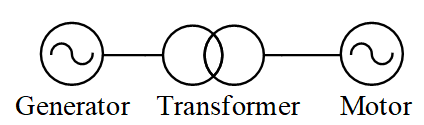                        

Find the subtransient current in per unit in the fault, in the generator and in the motor. Use the terminal voltage of the generator as the reference phasor and obtain the solution

**[Q1] **by computing the voltages behind subtransient reactance in the generator and motor and 

**[Q2] ** by using Thévenin’s theorem

Created by: Professor Francisco Gonzalez-Longatt, January 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

Github: [https://github.com/fglongatt/ElectricalPowerAnalysis](https://github.com/fglongatt/ElectricalPowerAnalysis) 

% INPUT DATA
VT = 0.9;
I = 1.0;
PF = 0.8;
XG = 0.15;
XM = 0.35;
XT = 0.10;

Initially the pre-fault condition is represented by an equivalent circuit as shown below:

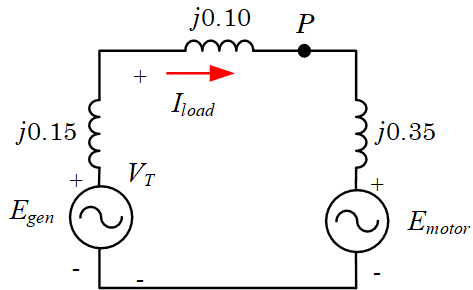

*Previous to the fault condi*tion, the terminal voltage of the generator is *V**T* = 0.9 per unit and the output current of the generator is 1.0 per unit at 0.8 power factor leading. Assuming the terminal voltage of the generator is selected as reference, *V**T* = 0.9 Ð0°p.u, the phasor diagram is depicted below:

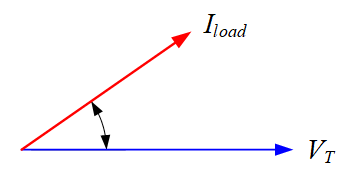

Remember, the power factor is leading!

As a consequence, the load current (*I**load*) is calculated as:

Angle = acos (PF)

Angle = 0.6435

Iload = I * exp(i*Angle);
fprintf(' Iload = (%5.5f + j%5.5f) pu',real(Iload),imag(Iload))

 Iload = (0.80000 + j0.60000) pu

fprintf(' Iload = (%5.5f < %5.5f) pu',abs(Iload),angle(Iload)*180/pi)

 Iload = (1.00000 < 36.86990) pu

The internal voltage of the generator (*E”**g*) is calculated by applying the KVL:

Eg = VT + i *XG * Iload;
fprintf(' Eg = (%5.5f + j%5.5f) pu',real(Eg),imag(Eg))

 Eg = (0.81000 + j0.12000) pu

fprintf(' Eg = (%5.5f < %5.5f) pu',abs(Eg),angle(Eg)*180/pi)

 Eg = (0.81884 < 8.42697) pu

The internal voltage of the motor (*E”**m*) is calculated as:

Em = VT - (i* XM + i* XT) * Iload;
fprintf(' Em = (%5.5f + j%5.5f) pu',real(Em),imag(Em))

 Em = (1.17000 + j-0.36000) pu

fprintf(' Em = (%5.5f < %5.5f) pu',abs(Em),angle(Em)*180/pi)

 Em = (1.22413 < -17.10273) pu

A three-phase fault occurs at the terminals of the motor, the situation is depicted below:

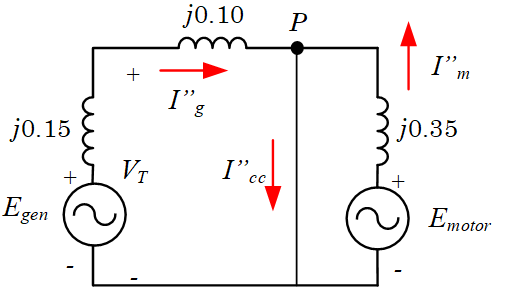

The current contribution of the generator (*I”**g*)to the short circuit is calculated as:

Ig = Eg /(i*XG + i*XT);
fprintf(' Ig = (%5.5f + j%5.5f) pu',real(Ig),imag(Ig))

 Ig = (0.48000 + j-3.24000) pu

fprintf(' Ig = (%5.5f < %5.5f) pu',abs(Ig),angle(Ig)*180/pi)

 Ig = (3.27536 < -81.57303) pu

The current contribution of the motor (*I”**m*) to the short circuit is calculated as:

Im = Em /(i*XM);
fprintf(' Im = (%5.5f + j%5.5f) pu',real(Im),imag(Im))

 Im = (-1.02857 + j-3.34286) pu

fprintf(' Im = (%5.5f < %5.5f) pu',abs(Im),angle(Im)*180/pi)

 Im = (3.49752 < -107.10273) pu

Finally, the three-phase short circuit current is calculated by using the KCL:

Icc = Ig + Im;
fprintf(' Icc = (%5.5f + j%5.5f) pu',real(Icc),imag(Icc))

 Icc = (-0.54857 + j-6.58286) pu

fprintf(' Icc = (%5.5f < %5.5f) pu',abs(Icc),angle(Icc)*180/pi)

 Icc = (6.60567 < -94.76364) pu

[Q2] The Thevenin method is applied, but the fault voltage must be calculated by using the load conditions. As a consequence, using the KVL:

Vf = VT - i * XT * Iload;
fprintf(' Vf = (%5.5f + j%5.5f) pu',real(Vf),imag(Vf))

 Vf = (0.96000 + j-0.08000) pu

fprintf(' Vf = (%5.5f < %5.5f) pu',abs(Vf),angle(Vf)*180/pi)

 Vf = (0.96333 < -4.76364) pu

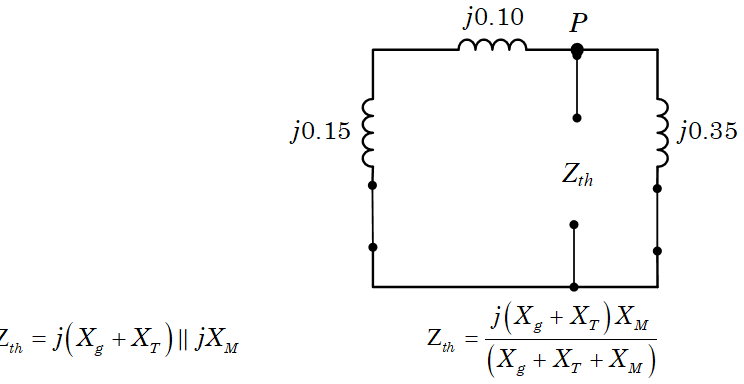

Zth = i* (XG + XT)*XM / (XG + XT +XM) ;
fprintf(' Zth = (%5.5f + j%5.5f) pu',real(Zth),imag(Zth))

 Zth = (0.00000 + j0.14583) pu

fprintf(' Zth = (%5.5f < %5.5f) pu',abs(Zth),angle(Zth)*180/pi)

 Zth = (0.14583 < 90.00000) pu

Finally, using the Thevenin method, the short circuit current is calculated as:

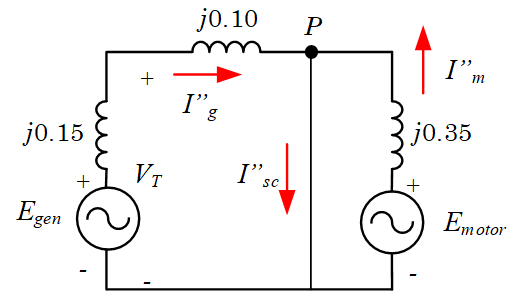

If = Vf / Zth;
fprintf(' If = (%5.5f + j%5.5f) pu',real(If),imag(If))

 If = (-0.54857 + j-6.58286) pu

fprintf(' If = (%5.5f < %5.5f) pu',abs(If),angle(If)*180/pi)

 If = (6.60567 < -94.76364) pu

By replacing *I”**sc* by a current source and then applying the principle of superposition,

Imm = -Iload + Vf / (i*XM);
fprintf(' Im = (%5.5f + j%5.5f) pu',real(Imm),imag(Imm))

 Im = (-1.02857 + j-3.34286) pu

fprintf(' Im = (%5.5f < %5.5f) pu',abs(Imm),angle(Imm)*180/pi)

 Im = (3.49752 < -107.10273) pu


Igg = Iload + Vf / (i*XG + i*XT);
fprintf(' Ig = (%5.5f + j%5.5f) pu',real(Igg),imag(Igg))

 Ig = (0.48000 + j-3.24000) pu

fprintf(' Ig = (%5.5f < %5.5f) pu',abs(Igg),angle(Igg)*180/pi)

 Ig = (3.27536 < -81.57303) pu